% Generate p1
p1 = [0 0; 0 -1; 0 -2; 0 -3]

p1 =      0     0
     0    -1
     0    -2
     0    -3


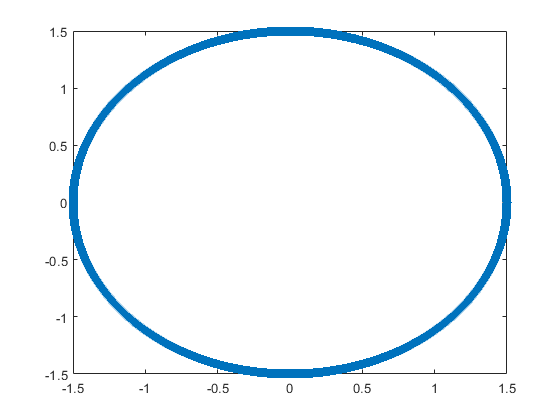

p2 =     1.5000         0
    1.5000    0.0015
    1.5000    0.0030
    1.5000    0.0045
    1.5000    0.0060
    1.5000    0.0075
    1.5000    0.0090
    1.5000    0.0105
    1.5000    0.0120
    1.4999    0.0135


%Generate p2 using circle function at the bottom of the file
p2 = circle(0, 0, 1.5)

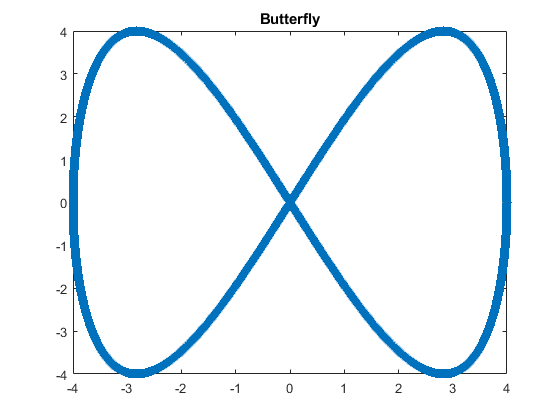

p3 =          0         0
         0         0
    0.0084   -0.0168
    0.0168   -0.0335
    0.0251   -0.0503
    0.0335   -0.0670
    0.0419   -0.0838
    0.0503   -0.1005
    0.0586   -0.1173
    0.0670   -0.1340


%Generate p3 and p4
p3 = butterfly(4, 4)

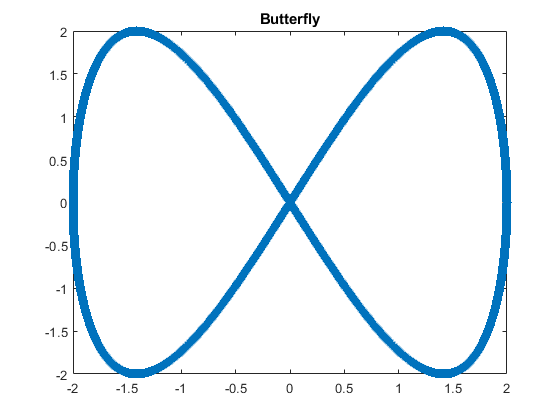

p4 = butterfly(2, 2);

function p=butterfly(h,w)
    freq = 2*pi/30;
    Ts = 0.01; %sampling time
    t = 0:Ts:30; %simulation time
    xRef = 0 + w * sin(freq*t);
    yRef = 0 - h * sin(2*freq*t);
    plot(xRef, yRef, '*');
    title('Butterfly');
    p = [0 xRef; 0 yRef]';
end

function p=circle(x,y,r)
%create and plot a circle with radius r and origin (x,y)
    ang=0:0.001:2*pi; 
    xp=r*cos(ang);
    yp=r*sin(ang);
    plot(x+xp,y+yp, '*');
    p=[xp;yp]';
end